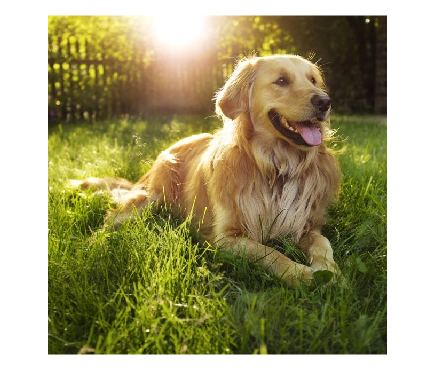

img = imread("squaredog.jpg");
imshow(img);

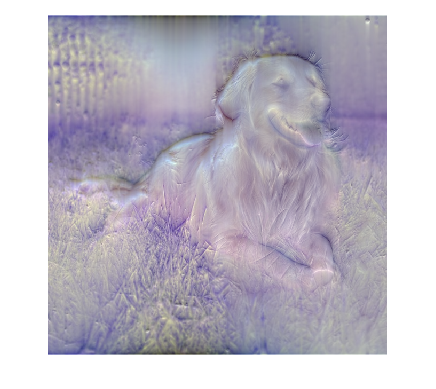


R = im2double(img(:,:,1));
G = im2double(img(:,:,2));
B = im2double(img(:,:,3));

% plot(1:635,R(:,1));

for i = 1:635

    Rv(:,i) = (hilbert(R(:,i)));
    Gv(:,i) = (hilbert(G(:,i)));
    Bv(:,i) = (hilbert(B(:,i)));
    
    Ro(i,:) = (hilbert(R(i,:)));
    Go(i,:) = (hilbert(G(i,:)));
    Bo(i,:) = (hilbert(B(i,:)));

end
% plot(1:635,real(RR));
% hold on
% plot(1:635,imag(RR));


Rv = rescale(imag(Rv),0,0.5);
Gv = rescale(imag(Gv),0,0.5);
Bv = rescale(imag(Bv),0,0.5);

%Ro = rescale(imag(Ro),0,0.5);
%Go = rescale(imag(Go),0,0.5);
%Bo = rescale(imag(Bo),0,0.5);


%outimg = cat(3,Rv.*Ro,Gv.*Go,Bv.*Bo);
outimg = cat(3,Rv,Gv,Bv);
outimg = rescale(outimg,0,1);
imshow(outimg);

%colormap("gray")

%imshow();

